# READ nwb file example created for the Neurolabware system and the SpecSeg toolbox

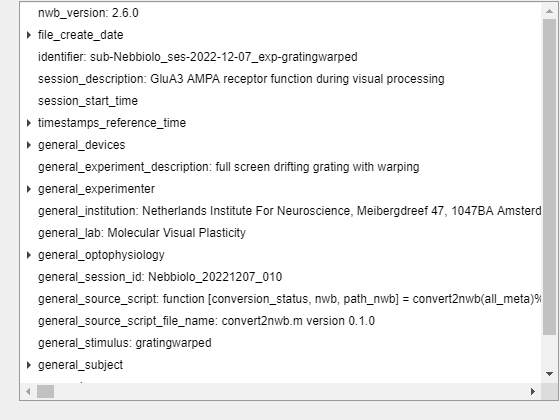


% matnwb needs to be installed. https://neurodatawithoutborders.github.io/matnwb/
% and added to your matlab path.

% First open the file and display it's contents
[fn, pn] = uigetfile('*.nwb');
nwb = nwbRead(fullfile(pn, fn), 'ignorecache');

util.nwbTree(nwb);


% As you can see there is quit alot of general metadata included. 
% get functions obtain an interface from which other objects can be retrieved
% NWB files are quit convoluted, but they follow a standard structure to
% enable access to any nwb file.

## General access into NWB file (hdf5) data

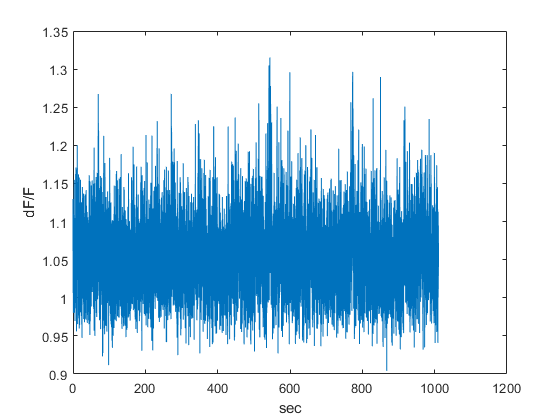

% The  actual data is in the processing interface. 
% The next lines all start with 'nwb.processing'
roidata = nwb.processing.get('ophys').nwbdatainterface.get('Fluorescence') ...
    .roiresponseseries.get('Corrected').data.load;

starting_time = nwb.processing.get('ophys').nwbdatainterface.get('Fluorescence') ...
    .roiresponseseries.get('Corrected').starting_time;
frame_rate= nwb.processing.get('ophys').nwbdatainterface.get('Fluorescence') ...
    .roiresponseseries.get('Corrected').starting_time_rate;

frametimes = (0:length(roidata)-1)/frame_rate + starting_time;

plot(frametimes , roidata(5,:))
xlabel('sec')
ylabel('dF/F')

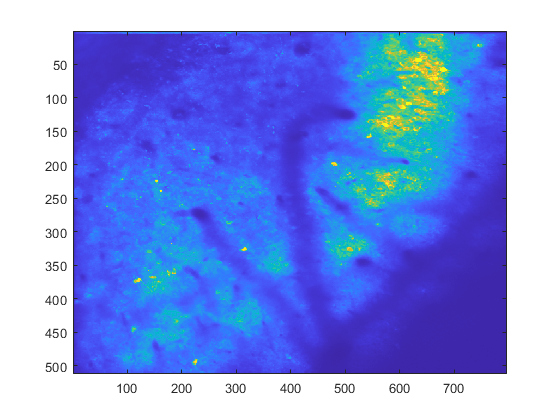



% mask = nwb.processing.get('ophys').nwbdatainterface.get('ImageSegmentation') ...
%     .planesegmentation.get('PlaneSegmentation').image_mask.data.load;
% imagesc(mask)

avgimg = nwb.processing.get('ophys').nwbdatainterface.get('SummaryImages') ...
    .image.get('avg_image').data.load;
imagesc(avgimg)

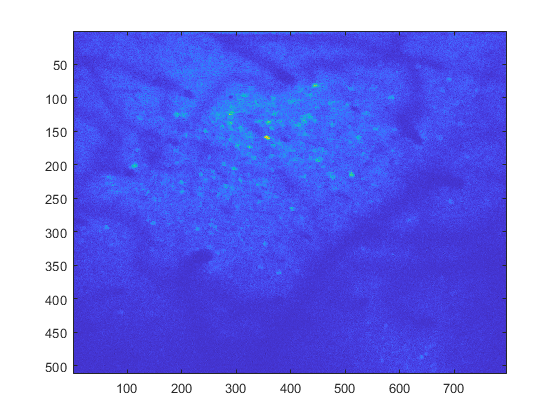

%% only for aquistion nwb files
data = nwb.acquisition.get('2pInternal').data.load;

for i = 1:500
    imagesc(data(:,:,i))
    drawnow()
    pause(0.03)
end